# Lecture 7

## Periodogram

A periodogram can estimate the Power Spectrum Density of a signal from a finite set of $N$ observations given by:

        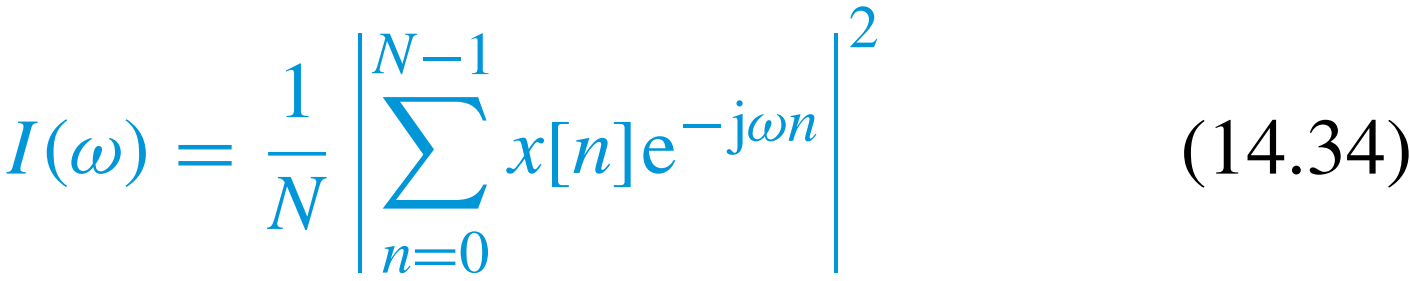

The periodogram can estimate of a zero-mean wide-sense stationary process (with absolute summable autocorrelation sequence) is a continous ("smooth") function of $\omega$ defined by:

        
$$S_{\mathrm{xx}} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\mathrm{xx}} \left(\ell \right)e^{-j\omega \ell }$$


## Modified Periodogram

        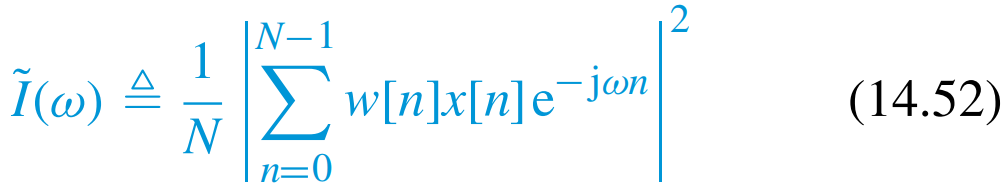

## Functions

function r=acrs(x, L)
    % Computes the ACRS r[m] for 0<= m <= L
    % r=acrs(x-mean(x),L) yields the ACVS
    N=length(x);
    x1=zeros(N+L-1,1);
    x2=x1;
    x1(1:N,1)=x;
    for m=1:L
        x2=zeros(N+L-1,1);
        x2(m:N+m-1,1)=x;
        r(m)=x1'*x2;
    end
    r=r(:)/N;
end


function I=psdper(x, K)
    % Compute periodogram I(ω) using the FFT.
    % K-point FFT >= N
    N=length(x);
    X=fft(x,K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function r=acrsfft(x, L)
    % Computate the autocorrelation sequence using the FFT.
    % r=acrsfft(x-mean(x),L) yields the ACVS
    N=length(x);
    Q=nextpow2(N+L);
    X=fft(x,2^Q);
    r0=real(ifft(X.*conj(X)));
    r=r0(1:L)/N;
end

function I=psdmodper(x, K)
    % Compute the modified periodogram PSD estimate.
    % K-point FFT >= N
    N=length(x);
    w=hann(N); % choose window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    X=fft(x(:).*w(:),K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function psdbt(x, L, K)
    % Computate the Blackman–Tukey PSD estimate.
    % Blackman–Tukey PSD estimator of S(2*pi*k/K)
    N=length(x);
    w=hann(N); % Data window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    x=x.*w; % Data windowing
    r=acrsfft(x,L);
    wc=parzenwin(2*L-1); % Lag window
    rw=r.*wc(L:2*L-1); % Lag windowing
    g=zeros(K,1);
    g(1:L)=rw;
    g(K-L+2:K)=flipud(rw(2:L));
    G=fft(g,K); % f even => F real
    S=2*real(G(1:K/2)); S(1)=S(2);
end

function S=psdwelch(x, L, K)
    % Compute the Welch PSD estimate.
    % Welch PSD estimator of S(2*pi*k/K)
    M=fix((length(x)-L/2)/(L/2)) % 50% overlap
    time=(1:L)’;
    I=zeros(K,1);
    w=hanning(L); % Choose window
    w=w/(norm(w)/sqrt(L)); % sum wˆ2[k]=L
    for m=1:M
    %xw=w.*detrend(x(time)); % detrenting
    xw=w.*x(time); % data windowing
    X=fft(xw,K);
    I=I+X.*conj(X);
    time=time+L/2;
    end
    I=I/(M*L); S=2*I(1:K/2); S(1)=S(2);
end